let $h$ be the step size

**(a.1)** $y'=x-2y=f(x,y)$. $y(0)=1$


$$y''=1-2y'=1-2x+4y$$



$$y'''=-2+4y'=-2+4x-8y$$



$$y''''=4-8y'=4-8x+16y$$


thus


$$y(x_{n+1})\approx y(x_n)+(x_n-2y_n)h+\frac{1-2x_n+4y_n}{2}h^2+\frac{-2+4x_n-8y_n}{6}h^3+\frac{4-8x_n+16y_n}{24}h^4}$$



$$x_0=0,y_0=1$$


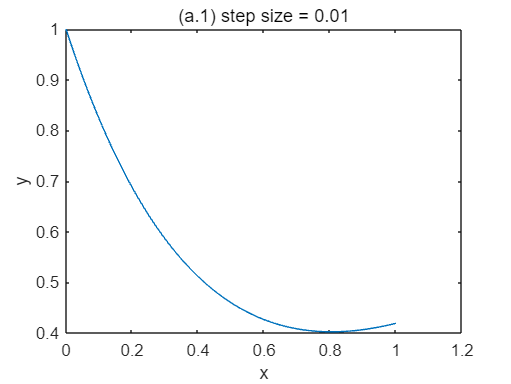

h = 0.01;
xs = [0];
ys = [1];

n = 100;

for i = 1:100
    x0 = xs(end);
    y0 = ys(end);

    y1 = y0 + (x0 - 2*y0)*h + (1-2*x0+4*y0)*h^2/2+(-2+4*x0-8*y0)*h^3/6+(4-8*x0+16*y0)*h^4/24;
    ys = [ys;y1];
    xs = [xs;x0+h];
end

figure(1);
plot(xs, ys)
title("(a.1) step size = 0.01")
xlabel("x")
ylabel("y")

**(a.2)** $y'=y(2-y), y(0)=4$


$$y''=2y(y-1)(y-2)$$



$$y'''=-2y(y-2)(3y^2-6y+2)$$



$$y''''=8y(y-1)(y-2)(3y^2-6y+1)$$


thus


$$y(x_{n+1})\approx y(x_n)+y_n(2-y_n)h+\frac{2y_n(y_n-1)(y_n-2)}{2}h^2+\frac{-2y_n(y_n-2)(3y_n^2-6y_n+2)}{6}h^3+\frac{8y_n(y_n-1)(y_n-2)(3y_n^2-6y_n+1)}{24}h^4$$



$$x_0=0,y_0=4$$


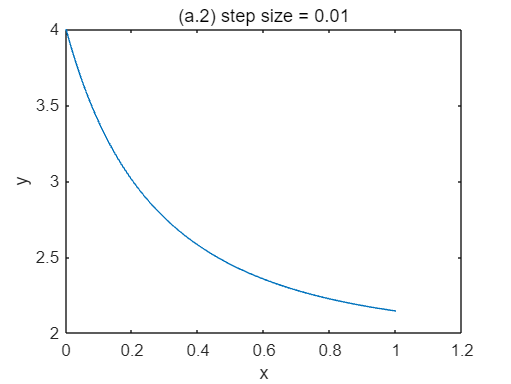

h = 0.01;
xs = [0];
ys = [4];

n = 100;

for i = 1:100
    x0 = xs(end);
    y0 = ys(end);

    y1 = y0 + (y0*(2-y0))*h + (2*y0*(y0-1)*(y0-2))*h^2/2 ...
        +(-2*y0*(y0-2)*(3*y0^3-6*y0+2))*h^3/6 ...
        +(8*y0*(y0-1)*(y0-2)*(3*y0^2-6*y0+1))*h^4/24;
    ys = [ys;y1];
    xs = [xs;x0+h];
end

figure(2);
plot(xs, ys)
title("(a.2) step size = 0.01")
xlabel("x")
ylabel("y")

**(b)** $y'=-y+\cos x-\sin x$, $y(0)=2$


$$y''=-2\cos x+y$$



$$y'''=-y+\sin x+\cos x$$



$$y''''=y$$



$$y'''''=-y+\cos x-\sin x$$


thus


$$y(x_{n+1})\approx y_n(x_n)+(-y_n+\cos x_n-\sin x_n)h+\frac{-2\cos x_n+y_n}{2}h^2\qquad\text{(degree 2)}$$



$$y(x_{n+1})\approx y_n(x_n)+(-y_n+\cos x_n-\sin x_n)h+\frac{-2\cos x_n+y_n}{2}h^2+\frac{-y_n+\sin x_n+\cos x_n}{6}h^3+\frac{y_n}{24}h^4+\frac{-y_n+\cos x_n-\sin x_n}{120}h^5 \qquad\text{(degree 5)}$$



$$x_0,y_0=2$$


for Euler method


$$y(x_{n+1})\approx y_n+(-y_n+\cos x_n-\sin x_n)h$$


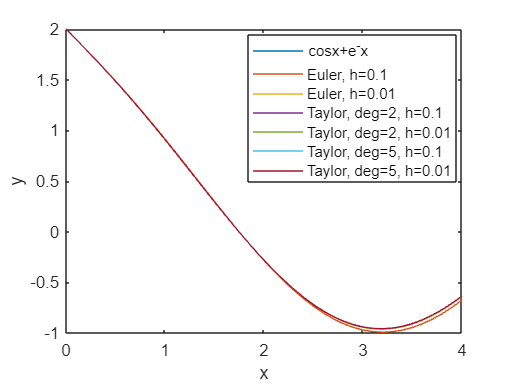

h1 = 0.1;
h2 = 0.01;

y0 = 2;
yse1 = [y0]; % Euler step size = 0.1
yse2 = [y0]; % Euler step size = 0.01
yst21 = [y0]; % Taylor degree 2, step size = 0.1
yst22 = [y0]; % Taylor degree 2, step size = 0.01
yst51 = [y0]; % Taylor degree 5, step size = 0.1
yst52 = [y0]; % Taylor degree 5, step size = 0.01

n11 = 1 / h1 + 1;
n12 = 4 / h1 + 1;
n21 = 1 / h2 + 1;
n22 = 4 / h2 + 1;

xs1 = (0:h1:4)';
xs2 = (0:h2:4)';

h = h1;
for i = 1:length(xs1)-1 % step 0.1
    x0 = xs1(i);

    y0 = yse1(end);    
    y1 = y0 + (-y0+cos(x0)-sin(x0))*h;
    yse1 = [yse1;y1];

    y0 = yst21(end);
    y1 = y0 + (-y0+cos(x0)-sin(x0))*h + (-2*cos(x0)+y0)*h^2/2;
    yst21 = [yst21;y1];

    y0 = yst51(end);
    y1 = y0 + (-y0+cos(x0)-sin(x0))*h + (-2*cos(x0)+y0)*h^2/2 ...
        + (-y0+sin(x0)+cos(x0))*h^3/6 + y0*h^4/24 ...
        + (-y0+cos(x0)-sin(x0))*h^5/120;
    yst51 = [yst51;y1];
end

h = h2;
for i = 1:length(xs2)-1 % step 0.01
    x0 = xs2(i);

    y0 = yse2(end);    
    y1 = y0 + (-y0+cos(x0)-sin(x0))*h;
    yse2 = [yse2;y1];

    y0 = yst22(end);
    y1 = y0 + (-y0+cos(x0)-sin(x0))*h + (-2*cos(x0)+y0)*h^2/2;
    yst22 = [yst22;y1];

    y0 = yst52(end);
    y1 = y0 + (-y0+cos(x0)-sin(x0))*h + (-2*cos(x0)+y0)*h^2/2 ...
        + (-y0+sin(x0)+cos(x0))*h^3/6 + y0*h^4/24 ...
        + (-y0+cos(x0)-sin(x0))*h^5/120;
    yst52 = [yst52;y1];
end

xs0 = 0:0.001:4;
ys0 = cos(xs0) + exp(-xs0);

figure(3);
plot(xs0, ys0, "DisplayName", "cosx+e^-x")
hold on
plot(xs1, yse1, "DisplayName", "Euler, h=0.1");
plot(xs2, yse2, "DisplayName", "Euler, h=0.01");
plot(xs1, yst21, "DisplayName", "Taylor, deg=2, h=0.1")
plot(xs2, yst22, "DisplayName", "Taylor, deg=2, h=0.01")
plot(xs1, yst51, "DisplayName", "Taylor, deg=5, h=0.1")
plot(xs2, yst52, "DisplayName", "Taylor, deg=5, h=0.01")
legend("Location", "best")
xlabel("x")
ylabel("y")
hold off

By calculation,** at **$x=1$, the 6 methods gives approximated values

- Euler, h=0.1 

- Euler, h=0.01

- Taylor, deg=2, h=0.1

- Taylor, deg=2, h=0.01

- Taylor, deg=5, h=0.1

- Taylor, deg=5, h=0.01

format long e;
res1 = [yse1(n11);yse2(n21);yst21(n11);yst22(n21);yst51(n11);yst52(n21)]

res1 =      9.153334504361821e-01
     9.088789721307721e-01
     9.082801705102947e-01
     9.081823425371728e-01
     9.081817490473297e-01
     9.081817470396023e-01


And the analytical solution gives

ana1 = cos(1)+exp(-1)

ana1 =      9.081817470395821e-01


hence the relative errors are

abs(res1 - ana1) / abs(ana1)

ans =      7.874749101611581e-03
     7.677153757634156e-04
     1.083742004653613e-04
     6.557031041684752e-07
     2.210733304603597e-09
     2.224891560972673e-14


**at **$x=4$, the 6 methods gives approximated values

format long e;
res2 = [yse1(n12);yse2(n22);yst21(n12);yst22(n22);yst51(n12);yst52(n22)]

res2 =     -6.753953797603721e-01
    -6.392728381771347e-01
    -6.351551291178738e-01
    -6.353260712490044e-01
    -6.353279935290940e-01
    -6.353279819749877e-01


And the analytical solution gives

ana2 = cos(4)+exp(-4)

ana2 =     -6.353279819748777e-01


hence the relative errors are

abs(res2 - ana2) / abs(ana2)

ans =      6.306569035562919e-02
     6.209164894633774e-03
     2.720686982283804e-04
     3.007463747087598e-06
     1.818622283016028e-08
     1.731752808972037e-13


Therefore, Taylor series approximation of degree 5 with step size 0.01 gives the closest approximation, and from the graph we can see that this method almost gives the closest approximation over the whole computation region, hence we can decide that it is of high possibility that this method also gives the closest approximation to $\phi(10)$.